# Example of function control

## Case setup

We use a some standard parameter set for the battery

jsonstruct = parseBattmoJson('Examples/jsondatafiles/sample_input.json');

## Functional time control

For a control that depends on time, we switch to a `timeControl` control policy

jsonstruct_control.controlPolicy = 'timeControl';

For this control policy, we have to add two functions in the `jsonstruct` structure of the control. The two functions are functions of time. We have

- a `type` function, whose value is either 1, for current, or 2, for voltage.

- a `value` function, which gives the value of the current or voltage, depending on the type, as a function of time

## Type control setup

We define the function as a constant equal to 1 for all time. In this case, the value of the control defined below will always correspond to a given control current. See `Utilities/JsonSchemas/Function.schema.json` for the syntax of a function to be used in json structures.

expression = struct('formula', '1');
jsonstruct_control.type = struct('functionFormat', 'string expression', ...
                                  'argumentList', {{'time'}}, ...
                                  'expression', expression);

## Value Control setup

We define the function for the control value, in this case a current, because of the type defined above. We use a sinusoidal. The `ampere` and `minute` are globally defined variables which can be used here (it would not work with local variables).

expression = struct('formula', '1e-2*ampere*sin(2*pi*time/(1*minute))');
jsonstruct_control.value = struct('functionFormat', 'string expression', ...
                                  'argumentList', {{'time'}}, ...
                                  'expression', expression);

## We finalize the setup of the `jsonstruct` input

jsonstruct.Control = jsonstruct_control;

We set the total time to 3 minutes

jsonstruct.TimeStepping.totalTime = 3*minute;

we set the initial state of charge to 0.5

jsonstruct.SOC = 0.5;

we run the simulation

output = runBattery(jsonstruct);

Solving timestep 001/150:                               -> 1 Second, 199 Milliseconds
Solving timestep 002/150: 1 Second, 199 Milliseconds    -> 2 Seconds, 399 Milliseconds
Solving timestep 003/150: 2 Seconds, 399 Milliseconds   -> 3 Seconds, 599 Milliseconds
Solving timestep 004/150: 3 Seconds, 599 Milliseconds   -> 4 Seconds, 799 Milliseconds
Solving timestep 005/150: 4 Seconds, 799 Milliseconds   -> 6 Seconds
Solving timestep 006/150: 6 Seconds                     -> 7 Seconds, 200 Milliseconds
Solving timestep 007/150: 7 Seconds, 200 Milliseconds   -> 8 Seconds, 400 Milliseconds
Solving timestep 008/150: 8 Seconds, 400 Milliseconds   -> 9 Seconds, 599 Milliseconds
Solving timestep 009/150: 9 Seconds, 599 Milliseconds   -> 10 Seconds, 799 Milliseconds
Solving timestep 010/150: 10 Seconds, 799 Milliseconds  -> 11 Seconds, 999 Milliseconds
Solving timestep 011/150: 11 Seconds, 999 Milliseconds  -> 13 Seconds, 199 Milliseconds
Solving timestep 012/150: 13 Seconds, 199 Milliseconds  -> 

We plot the results

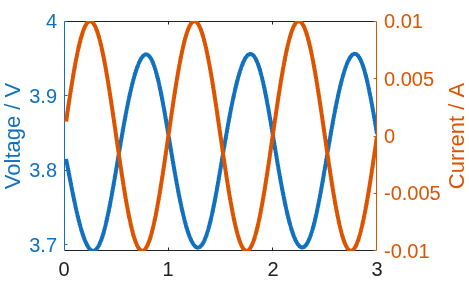

states = output.states;

time = cellfun(@(state) state.time, states);
E = cellfun(@(state) state.Control.E, states);
I = cellfun(@(state) state.Control.I, states);

figure
yyaxis left
plot(time/minute, E);
ylabel('Voltage / V')
yyaxis right
plot(time/minute, I);
ylabel('Current / A')

## Tabulated data for the function control

We change to tabulated data for the current control value

dataX = [0, 1*minute, 2*minute, 3*minute];
dataY = ampere*[0, 1e-2, 1e-2, 0];
expression = struct('formula', '1e-2*ampere*sin(2*pi*time/(1*minute))');
jsonstruct_control.value = struct('functionFormat', 'tabulated', ...
                                  'argumentList'  , {{'time'}} , ...
                                  'dataX'         , dataX      , ...
                                  'dataY'         , dataY);

We re-run the simulation

jsonstruct.Control = jsonstruct_control;

output = runBattery(jsonstruct);

Solving timestep 001/150:                               -> 1 Second, 199 Milliseconds
Solving timestep 002/150: 1 Second, 199 Milliseconds    -> 2 Seconds, 399 Milliseconds
Solving timestep 003/150: 2 Seconds, 399 Milliseconds   -> 3 Seconds, 599 Milliseconds
Solving timestep 004/150: 3 Seconds, 599 Milliseconds   -> 4 Seconds, 799 Milliseconds
Solving timestep 005/150: 4 Seconds, 799 Milliseconds   -> 6 Seconds
Solving timestep 006/150: 6 Seconds                     -> 7 Seconds, 200 Milliseconds
Solving timestep 007/150: 7 Seconds, 200 Milliseconds   -> 8 Seconds, 400 Milliseconds
Solving timestep 008/150: 8 Seconds, 400 Milliseconds   -> 9 Seconds, 599 Milliseconds
Solving timestep 009/150: 9 Seconds, 599 Milliseconds   -> 10 Seconds, 799 Milliseconds
Solving timestep 010/150: 10 Seconds, 799 Milliseconds  -> 11 Seconds, 999 Milliseconds
Solving timestep 011/150: 11 Seconds, 999 Milliseconds  -> 13 Seconds, 199 Milliseconds
Solving timestep 012/150: 13 Seconds, 199 Milliseconds  -> 

We plot the results

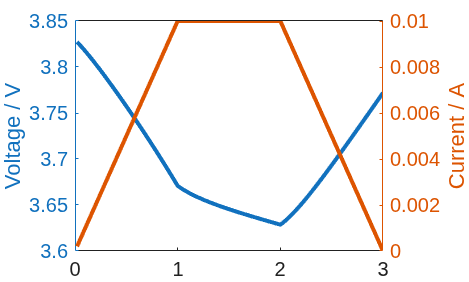

states = output.states;

time = cellfun(@(state) state.time, states);
E = cellfun(@(state) state.Control.E, states);
I = cellfun(@(state) state.Control.I, states);

figure
yyaxis left
plot(time/minute, E);
ylabel('Voltage / V')
yyaxis right
plot(time/minute, I);
ylabel('Current / A')